#### General parameters 

These are the same 'options' used for the filtering and segmentation

clear
addpath('./TimeFeatures')
addpath('./FreqFeatures')
addpath('./ReadWriteFunctions')
opts = readOptionsStruct()

opts = struct with fields:
              orig_file_dir: "../physionet.org/textdata/"
                abp_ann_dir: "../physionet.org/abp_ann/"
         segmented_file_dir: "../physionet.org/segmented_data/"
        clear_segmented_dir: 0
          segmented_abp_dir: "../physionet.org/segmented_abp_beats/"
       first_record_process: 180
        last_record_process: 185
               apply_filter: 0
                  samp_freq: 125
                     filter: [1×1 struct]
           apply_hampel_abp: 0
           apply_hampel_ppg: 1
                      flats: [1×1 struct]
          min_region_length: 7500
    num_periods_per_segment: 20
    normalisation_file_name: "NormalisationFactors.mat"
        bandwidth_criterion: 0.9900
        num_freq_components: 200


#### Systolic Peaks, Diastolic Peaks and Waveform Feet

See M. Elgendi "On the Analysis of Fingertip Photoplethysmogram Signals" p. 6

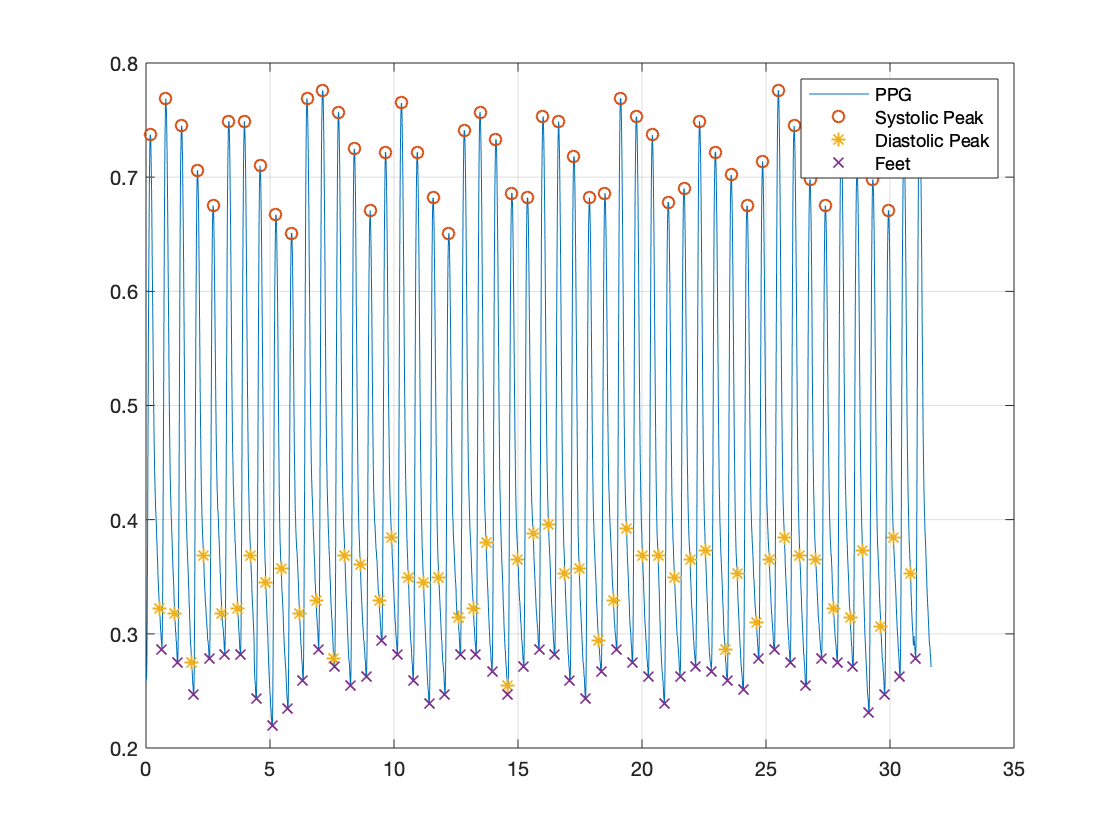


data = importdata("../physionet.org/segmented_data/3739816_0022-0012.txt");
[sys, dias, feet] = findPPGPeaks(data(:,3), opts.samp_freq);

%sort the peaks: foot - sys - dias - next foot
%   this avoids issues if any point could not be found for a waveform
sortedPeaks = sortPPGPeaks(systolic_pts, diastolic_pts, feet);

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(sortedPeaks(:,2),1), data(sortedPeaks(:,2),3), 'o', 'LineWidth',1);
scatter(data(sortedPeaks(:,3),1), data(sortedPeaks(:,3),3), '*', 'LineWidth',1)
scatter(data(sortedPeaks(:,1),1), data(sortedPeaks(:,1),3), 'x', 'LineWidth',1)
legend("PPG", "Systolic Peak", "Diastolic Peak", "Feet")
grid on

#### Systolic and Diastolic Peak Amplitudes

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0009.txt");
[systolic_pts, diastolic_pts, feet] = findPPGPeaks(data(:,3), opts.samp_freq);
disp('Systolic Points')

Systolic Points


mean_amp = mean(data(systolic_pts,3))

mean_amp = 2.6740

dev_amp = std(data(systolic_pts,3))

dev_amp = 0.4107

max_amp = max(data(systolic_pts,3))

max_amp = 3.3710

min_amp = min(data(systolic_pts,3))

min_amp = 1.5220


disp('Diastolic Pts')

Diastolic Pts


mean_amp = mean(data(diastolic_pts,3))

mean_amp = 1.6999

dev_amp = std(data(diastolic_pts,3))

dev_amp = 0.5306

max_amp = max(data(diastolic_pts,3))

max_amp = 2.7100

min_amp = min(data(diastolic_pts,3))

min_amp = 0.7050

#### Heart Rate extraction from PPG

First the ppg foot waveform locations are extracted

Then these are used to find the HR (mean, max, most recent)

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0005-0015.txt");

[sys,dias,feet] = findPPGPeaks(data(:,3), opts.samp_freq);
sortedFeatures = sortPPGPeaks(sys, dias, feet);
[hr_avg, hr_max, hr_most_rec] = heartRateFromPPG(sortedFeatures(:,1), sortedFeatures(:,4), opts.samp_freq)

hr_avg = 75.7632

hr_max = 80.6452

hr_most_rec = 74.2574

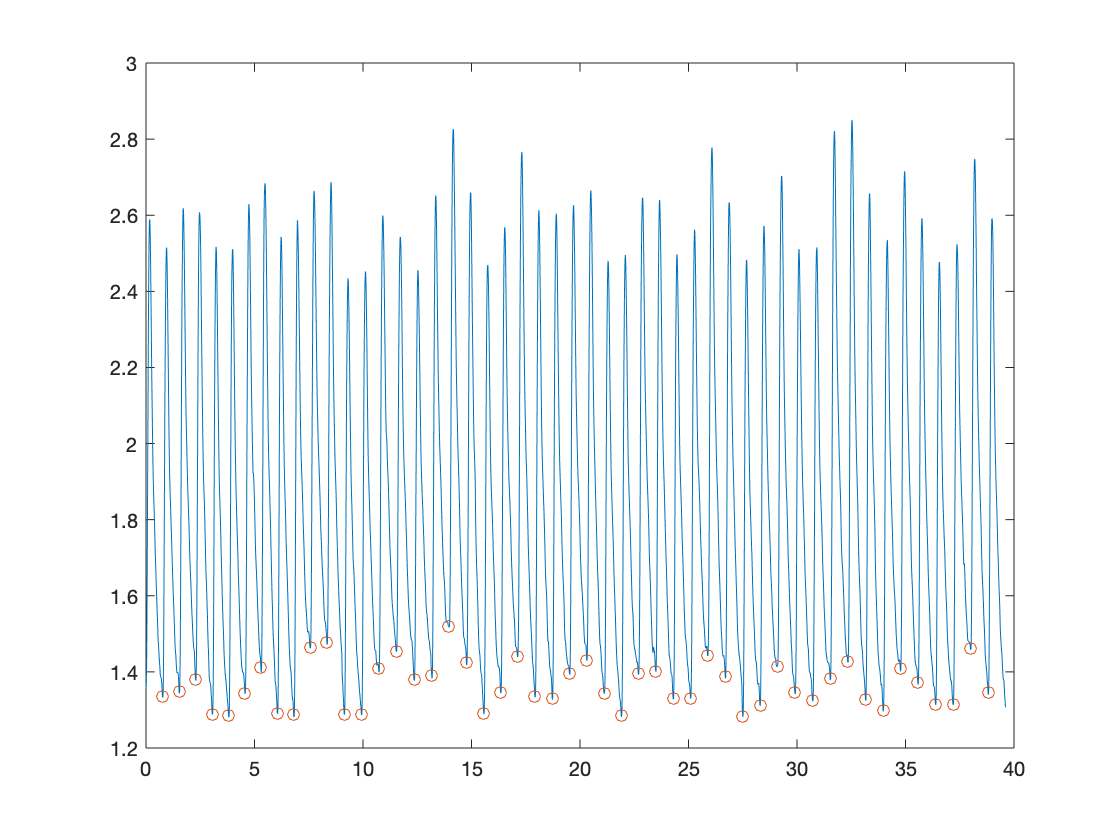


clf
plot(data(:,1), data(:,3))
hold on
scatter(data(ppg_feet,1), data(ppg_feet,3))

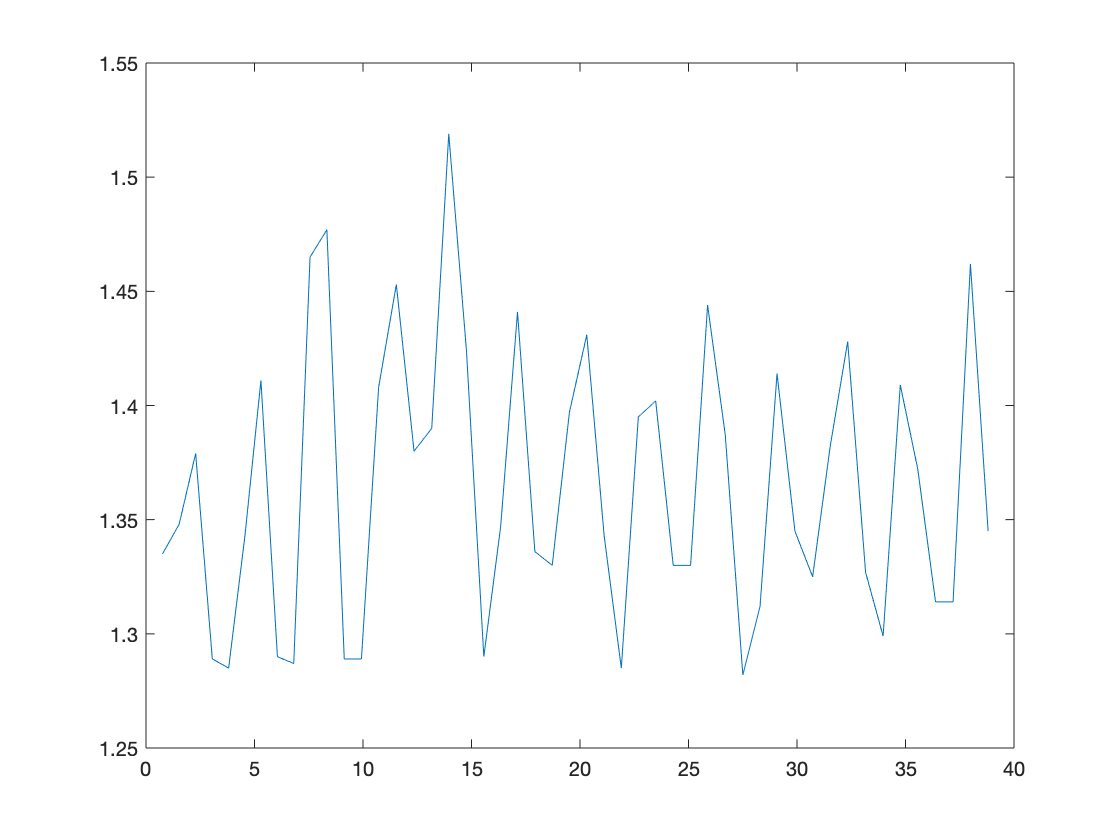

clf
plot(data(ppg_feet,1), data(ppg_feet,3))

#### PPG Time, Height, Area Intervals

Pulse Area (PA) - total area between feet

Inflection point area (IPA) - ratio of area in systole to ratio of area in diastole

Augmentation Index (AI) : height of diastolic peak:height of systolic peak

Peak-to-Peak time (ΔT) = time from systolic to diastolic peak (when no clear peak exists use the local max on the first derivative)

Large artery stiffness index(SI) = subject's height/ΔT (not currently possible)

Crest time (CT)= time between foot of wave to peak

        source: M. Elgendi, "On the analysis of fingertip photoplethysmogram signals"

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3003005_0003-0002.txt");
[systolic_pts, diastolic_pts, feet] = findPPGPeaks(data(:,3), opts.samp_freq);

sortedPeaks = sortPPGPeaks(systolic_pts, diastolic_pts, feet);

[PA, IPA, AI] = ppgAreaAndHeightFeatures(data(:,3), sortedPeaks);
deltaT = (sortedPeaks(:,3)-sortedPeaks(:,2))./opts.samp_freq;
CT = (sortedPeaks(:,2)-sortedPeaks(:,1))./opts.samp_freq;

fprintf('PA - mean: %.4f \t std dev: %.4f', mean(PA), std(PA))

PA - mean: 48.2418 	 std dev: 10.1634

fprintf('IPA - mean: %.4f \t std dev: %.4f', mean(IPA), std(IPA))

IPA - mean: 0.1098 	 std dev: 0.1470

fprintf('AI - mean: %.4f \t std dev: %.4f', mean(AI), std(AI))

AI - mean: 0.4660 	 std dev: 0.1542

fprintf('ΔT - mean: %.4f s \t std dev: %.4f s', mean(deltaT), std(deltaT))

ΔT - mean: 0.2764 s 	 std dev: 0.0773 s

fprintf('CT - mean: %.4f s \t std dev: %.4f s', mean(CT), std(CT))

CT - mean: 0.1447 s 	 std dev: 0.0308 s

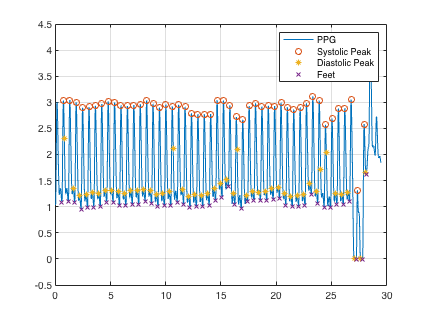


clf
plot(data(:,1), data(:,3))
hold on
scatter(data(sortedPeaks(:,2),1), data(sortedPeaks(:,2),3), 'o', 'LineWidth',1);
scatter(data(sortedPeaks(:,3),1), data(sortedPeaks(:,3),3), '*', 'LineWidth',1)
scatter(data(sortedPeaks(:,1),1), data(sortedPeaks(:,1),3), 'x', 'LineWidth',1)
legend("PPG", "Systolic Peak", "Diastolic Peak", "Feet")
grid on

%ABP Systolic, Diastolic and Mean

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3003005_0003-0002.txt");
[systolic_pts, diastolic_pts, meanSBP, meanDBP, MAP] = findABPPeaks(data(:,2), opts.samp_freq);

meanSBP

meanSBP = 101.0087

meanDBP

meanDBP = 65.4492

MAP

MAP = 76.7676

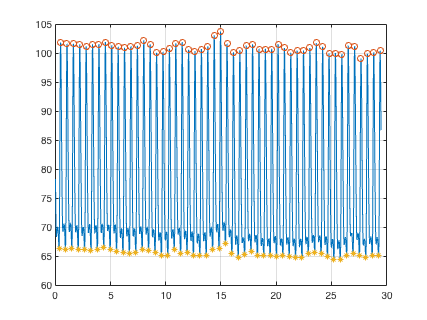

clf
plot(data(:,1), data(:,2))
hold on
scatter(data(systolic_pts,1), data(systolic_pts,2), 'o', 'LineWidth',1);
scatter(data(diastolic_pts,1), data(diastolic_pts,2), '*', 'LineWidth',1)
grid on

#### Respiratory rate from PPG

See P.S.Addison et al. [https://sci-hub.se/10.1007/s10877-011-9332-y](https://sci-hub.se/10.1007/s10877-011-9332-y)

Typical freq range of respiration is [2.97;28.02] breaths/min <=> [0.05;0.47] Hz. A heart rate of [45;220] bpm <=> [0.75; 3.67] Hz ie. signals should be able to be separated

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3161587_0039-0024.txt");


resp_rate_hz = getRespiratoryRateFreq(data(:,1), data(:,3))

resp_rate_hz = 0.2446

resp_rate_bpm = resp_rate_hz*60

resp_rate_bpm = 14.6758

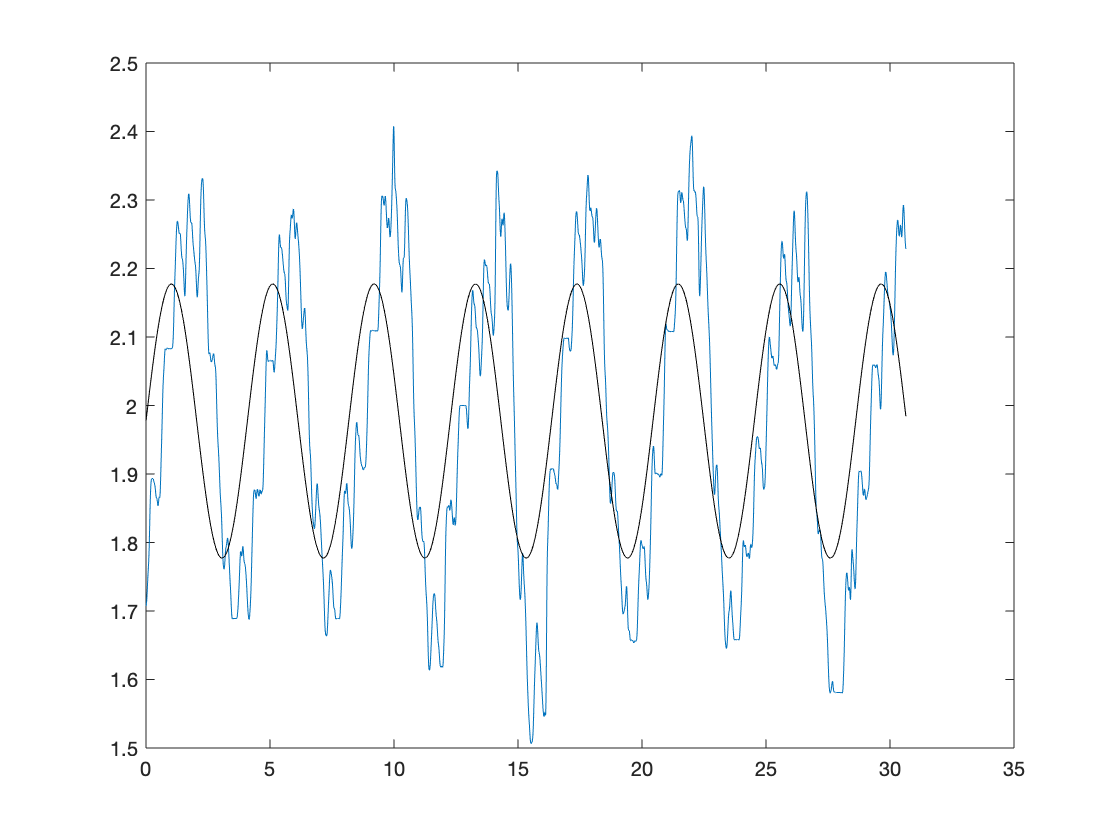


clf
plot(data(:,1), data(:,3))
hold on
plot(data(:,1), 0.2.*sin(2*pi*resp_rate_hz.*data(:,1))+mean(data(:,3)), 'Color', 'black')

#### Feature Scaling Factors

Roughly, the range of features should not be greater than [-1,1] and not smaller than [-1/3; 1/3] 

Normalisation should not be applied alone on each signal because every signal should have the same shift and scaling applied ie. need to calculate every feature's mean and std deviation across all files. This includes for the input ppg waveform and output ABP waveform.

Averaging standard deviations is done by averaging the variances and then square rooting.

addpath('./TimeFeatures')

%Structure of each scaling variable = [mean, variance] where each row represents
%   a different file
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList)

numFiles = 1302

ppg = zeros(numFiles,2);
abp = zeros(numFiles,2);
systolic_peak_amplitudes = zeros(numFiles,2);
diastolic_peak_amplitudes = zeros(numFiles,2);
feet_amplitudes = zeros(numFiles,2);
%the features below will be single valued ie just store the mean and the
%variance is calculated at the end
PA = zeros(numFiles,1);
IPA = zeros(numFiles,1);
AI = zeros(numFiles,1);
deltaT = zeros(numFiles,1);
CT = zeros(numFiles,1);
heart_rate = zeros(numFiles,1);
resp_rate = zeros(numFiles,1);

pkABPFreqs = zeros(numFiles,1);
pkABPMags = zeros(numFiles,opts.num_freq_components+1);
ABPPower = zeros(numFiles,1);
ABPBW = zeros(numFiles,1);
pkPPGFreqs = zeros(numFiles,1);
pkPPGMags = zeros(numFiles,opts.num_freq_components+1);
PPGPower = zeros(numFiles,1);
PPGBW = zeros(numFiles,1);


numWorkers = 8;

% for (idx = 1:numFiles)
parfor (idx = 1:numFiles, numWorkers)
    fprintf('\b\b\b\b\b %i', idx)
    
     dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
     data = cell2mat(textscan( dataFile, ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
     fclose(dataFile);
     
     abp_wave = data(:,2);
     ppg_wave = data(:,3);
     
     abp(idx,:) = [mean(abp_wave), max(abp_wave)];
     ppg(idx,:) = [mean(ppg_wave), max(ppg_wave)];
     
    [sys,dias,feet] = findPPGPeaks(ppg_wave, opts.samp_freq);
    sortedFeatures = sortPPGPeaks(sys, dias, feet);
     
%     systolic_peak_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,2))), std(ppg_wave(sortedFeatures(:,2)))^2];
%     diastolic_peak_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,3))), std(ppg_wave(sortedFeatures(:,3)))^2];
%     feet_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,1))), std(ppg_wave(sortedFeatures(:,1)))^2];

    systolic_peak_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,2))), max(ppg_wave(sortedFeatures(:,2)))];
    diastolic_peak_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,3))), max(ppg_wave(sortedFeatures(:,3)))];
    feet_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,1))), max(ppg_wave(sortedFeatures(:,1)))];
   
    heart_rate = [heart_rate; heartRateFromPPG(sortedFeatures(:,1), sortedFeatures(:,4), opts.samp_freq)];
    
    resp_rate = [resp_rate; getRespiratoryRateFreq(data(:,1), ppg_wave)];
    
    [currPA, currIPA, currAI] = ppgAreaAndHeightFeatures(data(:,3), sortedFeatures);
    PA(idx,:) = [mean(currPA)];
    IPA(idx,:) = [mean(currIPA)];
    AI(idx,:) = [mean(currAI)];
    deltaT(idx,:) = [mean((sortedFeatures(:,3)-sortedFeatures(:,2))./opts.samp_freq)];
    CT(idx,:) = [mean((sortedFeatures(:,2)-sortedFeatures(:,1))./opts.samp_freq)];

    [pkIndices, pkFreqsCurr, pkMags, pkPhases,power, bandwidth] = extractNFrequencyComponents(data(:,1), data(:,2), opts.num_freq_components, opts.bandwidth_criterion);
    pkABPFreqs(idx, :) = max(pkFreqsCurr);
    if(numel(pkMags) < opts.num_freq_components)
        pkMags = zeropad(pkMags, opts.num_freq_components-numel(pkMags)+1, 0, "post" );
    end
    pkABPMags(idx, :) = pkMags';
    ABPPower(idx, :) = power;
    ABPBW(idx,:) = bandwidth;

    [pkIndices, pkFreqsCurr, pkMags, pkPhases,power, bandwidth] = extractNFrequencyComponents(data(:,1), data(:,3), opts.num_freq_components, opts.bandwidth_criterion);
    pkPPGFreqs(idx, :) = max(pkFreqsCurr);
    if(numel(pkMags) < opts.num_freq_components)
        pkMags = zeropad(pkMags, opts.num_freq_components-numel(pkMags)+1,"post" );
    end
    pkPPGMags(idx, :) = pkMags';
    PPGPower(idx, :) = power;
    PPGBW(idx,:) = bandwidth;

end

 1302


normFactors = containers.Map();
normFactors('PPGAmpMean') = mean(ppg(:,1));
normFactors('PPGAmpScale') = max(ppg(:,2))-mean(ppg(:,1));
normFactors('ABPAmpMean') = mean(abp(:,1));
normFactors('ABPAmpScale') = max(abp(:,2))-mean(abp(:,1));
normFactors('sysPeakAmpMean') = mean(systolic_peak_amplitudes(:,1));
normFactors('sysPeakAmpScale') = max(systolic_peak_amplitudes(:,2))-mean(systolic_peak_amplitudes(:,1));
normFactors('diasPeakAmpMean') = mean(diastolic_peak_amplitudes(:,1));
normFactors('diasPeakAmpScale') = max(diastolic_peak_amplitudes(:,2))-mean(diastolic_peak_amplitudes(:,1));
normFactors('feetAmpMean') = mean(feet_amplitudes(:,1));
normFactors('feetAmpScale') = max(feet_amplitudes(:,2))-mean(feet_amplitudes(:,1));;
%the features below will be single valued ie just store the mean and the
%variance is calculated at the end
normFactors('PAMean') = mean(PA) ;
normFactors('PAScale') = max(PA)-mean(PA);
normFactors('IPAMean') = mean(IPA) ;
normFactors('IPAScale') = max(IPA)-mean(IPA);
normFactors('AIMean') = mean(AI) ;
normFactors('AIScale') = max(AI)-mean(AI);
normFactors('deltaTMean') = mean(deltaT);
normFactors('deltaTScale')=   max(deltaT)-mean(deltaT);
normFactors('CTMean') = mean(CT);
normFactors('CTScale') = max(CT)- mean(CT);
normFactors('HRMean') = mean(heart_rate);
normFactors('HRScale') = max(heart_rate)-mean(heart_rate);
normFactors('RRMean') = mean(resp_rate);
normFactors('RRScale') = max(resp_rate)-mean(resp_rate);

normFactors('FreqScalePPG') = max(pkPPGFreqs); 
normFactors('FreqScaleABP') = max(pkABPFreqs);
normFactors('PPGPower') = max(PPGPower); 
normFactors('ABPPower') = max(ABPPower);
normFactors('PPGBW') = max(PPGBW); 
normFactors('ABPBW') = max(ABPBW);
normFactors('pkPPGMags') = [max(pkPPGMags)];
normFactors('pkABPMags') = [max(pkABPMags)];

allKeys = normFactors.keys;
for i=1:normFactors.Count
    fprintf("\n %20s %.4f", allKeys{i}, normFactors(allKeys{i}))
end


           ABPAmpMean 90.7663
          ABPAmpScale 89.2337
                ABPBW 4.3246
             ABPPower 16071.5514
               AIMean 0.5612
              AIScale 0.3226
               CTMean 0.1666
              CTScale 0.1403
         FreqScaleABP 62.4459
         FreqScalePPG 62.0876
               HRMean 42.7135
              HRScale 77.6299
              IPAMean 0.1627
             IPAScale 0.7293
               PAMean 51.8786
              PAScale 53.6918
           PPGAmpMean 1.4364
          PPGAmpScale 2.7017
                PPGBW 4.2310
             PPGPower 4.4355
               RRMean 0.1260
              RRScale 0.2244
           deltaTMean 0.3319
          deltaTScale 0.3750
      diasPeakAmpMean 1.2469
     diasPeakAmpScale 2.7810
          feetAmpMean 0.8986
         feetAmpScale 3.0996
            pkABPMags 122.3178
         4.112701e+00 8.3099
         8.110648e+00 12.9337
         5.038211e+00 12.8336
         1.476636e+01 26.6370
         2.601432e+01 34.


save('NormalisationFactors', 'normFactors')

addpath('./TimeFeatures')

inputFeatFile = fopen("../physionet.org/inputFeatures.csv", 'w');
outputFeatFile = fopen("../physionet.org/outputFeatures.csv", 'w');

fileList = dir(opts.segmented_file_dir+"*.txt");

numFiles = length(fileList);

%Run the feature extraction once to get the column headings
[inputFeats, outputFeats] = fullInputOutputFeatureExtraction(fileList(1).name,opts);
writeMapKeysToFile(inputFeatFile, inputFeats, " %10s, ");
fprintf(inputFeatFile,"\n");
writeMapKeysToFile(outputFeatFile, outputFeats, " %10s, ");
fprintf(outputFeatFile,"\n");

%if we want to parallelise this we need to be careful about parallel file
%writing
for (idx = 1:numFiles)
    fprintf('\b\b\b\b\b %i', idx)

    [inputFeats, outputFeats] = fullInputOutputFeatureExtraction(fileList(idx).name,opts);
    
    writeMapValuesToFile(inputFeatFile, inputFeats, " %3.7f, ");
    fprintf(inputFeatFile,"\n");

    writeMapValuesToFile(outputFeatFile, outputFeats, " %3.7f, ");
    fprintf(outputFeatFile,"\n");
end

 35



fclose(outputFeatFile);
fclose(inputFeatFile);